Forår2016AltMatLab

clearvars
clc
close all

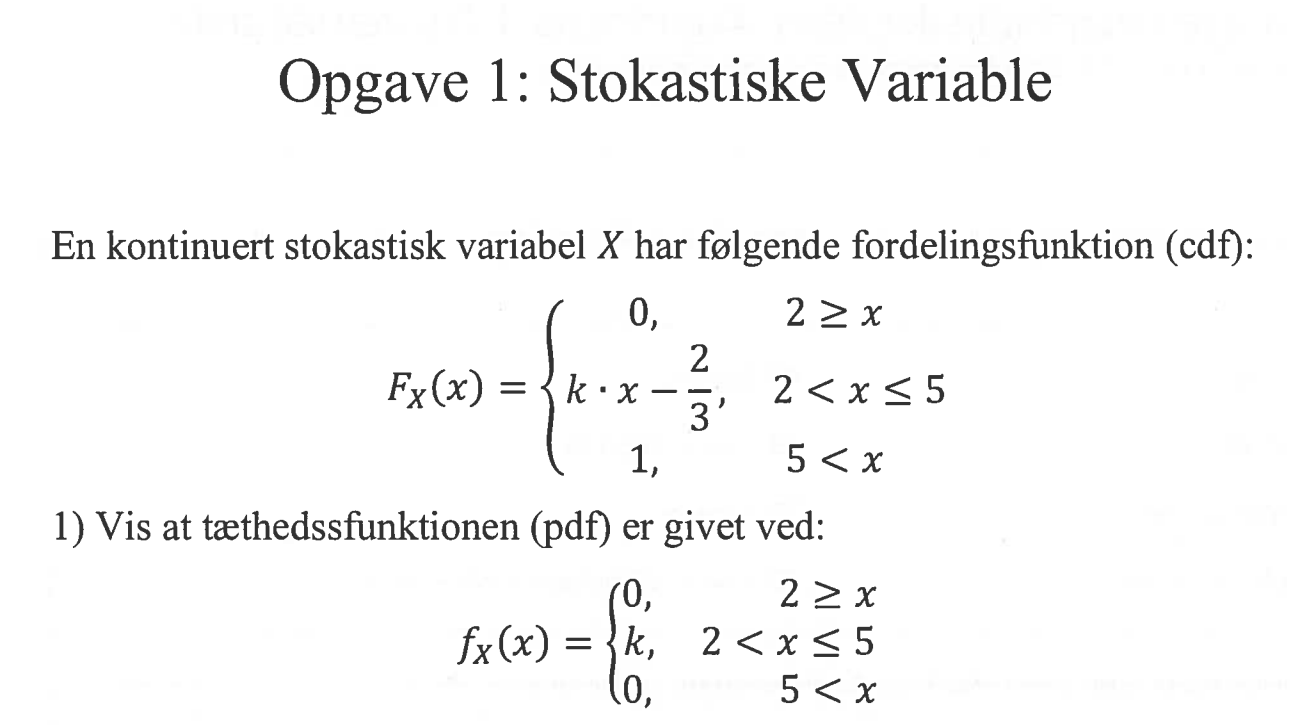

syms x k
Fx(x) = piecewise(2 >= x, 0, 2 < x <= 5, k * x -2/3, 5 < x, 1)

$$Fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x\leq 2\\ k\,x-\frac{2}{3} & \text{ if }x\in \left(2,5\right]\\ 1 & \text{ if }5<x \end{array}\right.$$


fx(x) = diff(Fx(x))

$$fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<2\\ k & \text{ if }x\in \left(2,5\right)\\ 0 & \text{ if }5<x \end{array}\right.$$

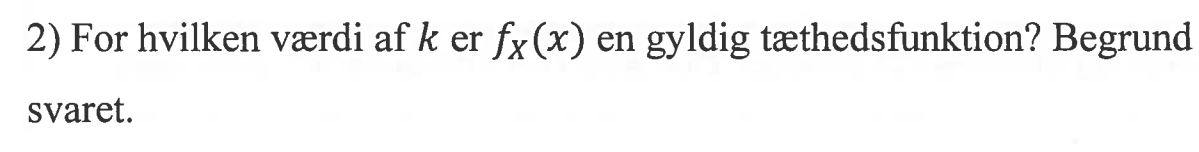

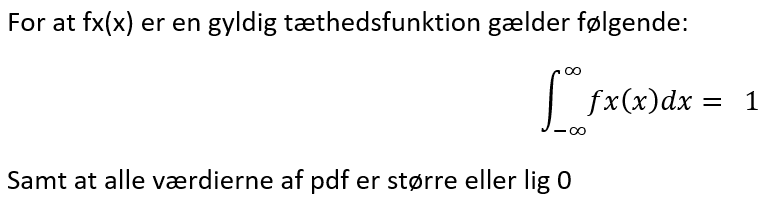

teathed = int(fx(x), 'x', -Inf, Inf)

$$teathed = 3\,k$$


k = solve(teathed==1, k)

$$k = \frac{1}{3}$$

clearvars
syms x
k = 1/3

k = 0.3333

Fx(x) = piecewise(2 >= x, 0, 2 < x <= 5, k * x -2/3, 5 < x, 1);
fx(x) = diff(Fx(x));

fplot(fx(x), [-4, 13],'-r','LineWidth',2)

title('Tæthedsfunktion')
xlabel('x')
ylabel('y')

Fordelingsfunktionen er uniform fordelt

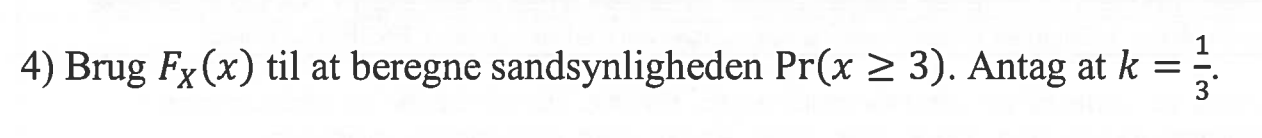

Pr=1-Fx(3)

$$Pr = \frac{2}{3}$$

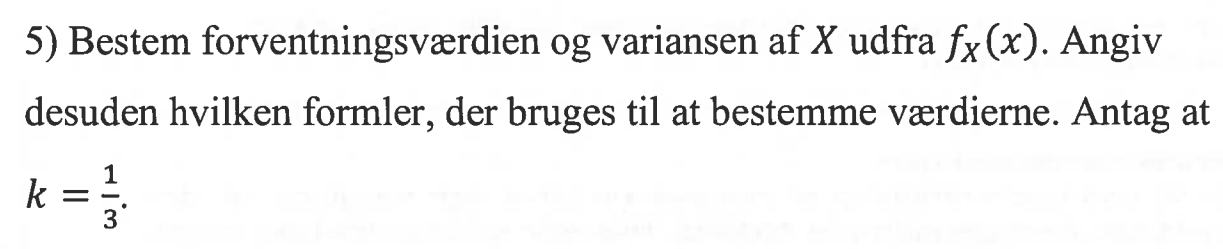

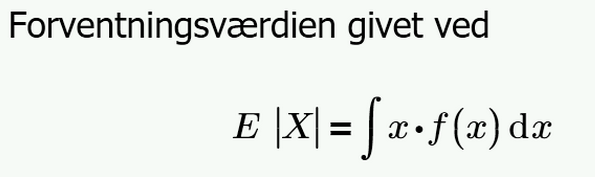

Ex=int(x*fx(x),'x',-Inf,Inf)

$$Ex = \frac{7}{2}$$

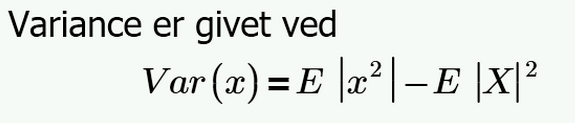

var = int(x^2*fx(x),'x',-Inf,Inf)-(Ex^2)

$$var = \frac{3}{4}$$

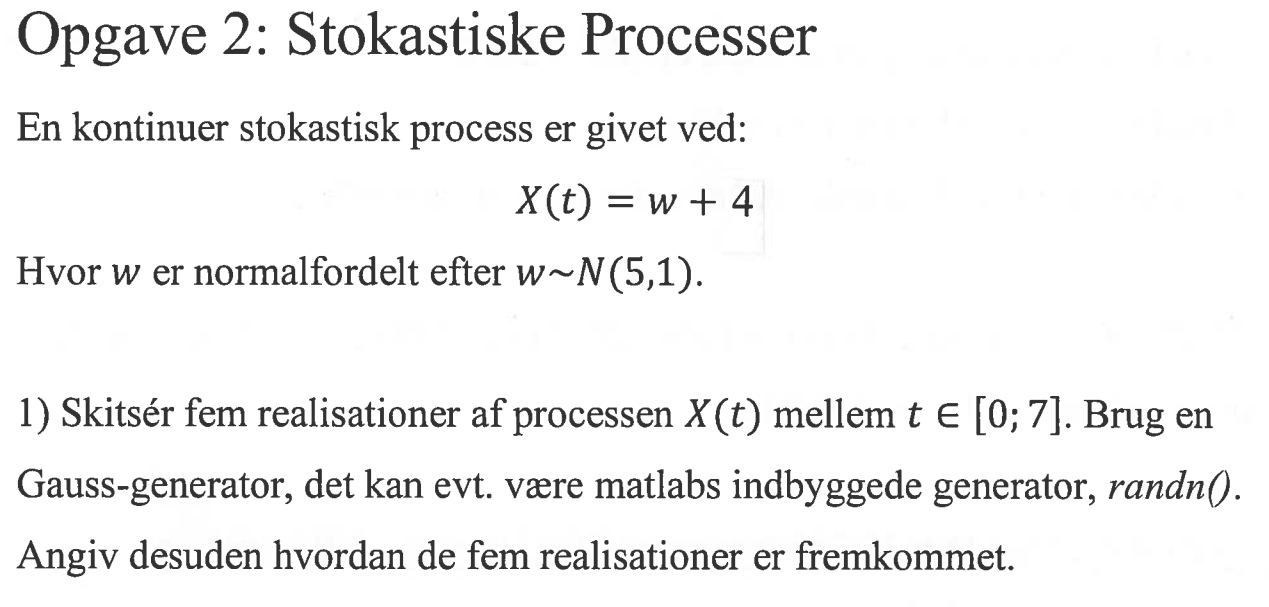

Normal fordelt - Middelværdi = 5, varians = 1

clearvars
close all
% Antal realisationer
N = 5;
t_start = 0;
t_end = 7;
interval = t_end-t_start;
mean = 5; variance = 1; sigma = sqrt(variance);
w = normrnd(mean, sigma, [1 N+1])

w =     4.2451    6.3703    3.2885    4.8978    4.7586    5.3192


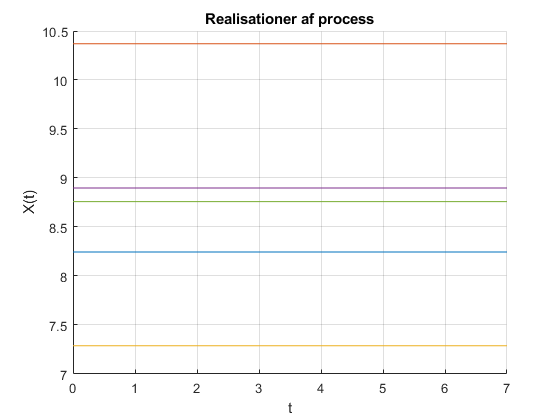

t = t_start:1:t_end;
figure(1)
hold on
grid
xlabel("t"); ylabel("X(t)"); title("Realisationer af process");
for i=1:N
    y = w(i)+4;
    fplot(y,[0 7])  
end

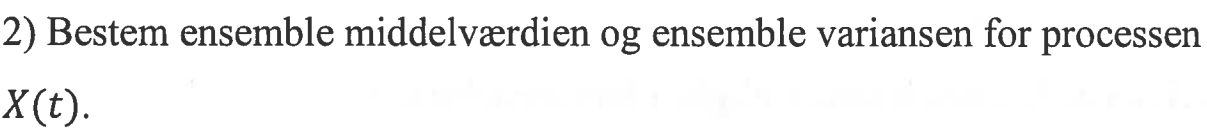

Vi kender middelværdien for normalfordelingen W.

ensembleMean = mean+4

ensembleMean = 9

Vi kender variansen for norfordelingen W

ensembleVar = variance + (4^2-4^2)

ensembleVar = 1

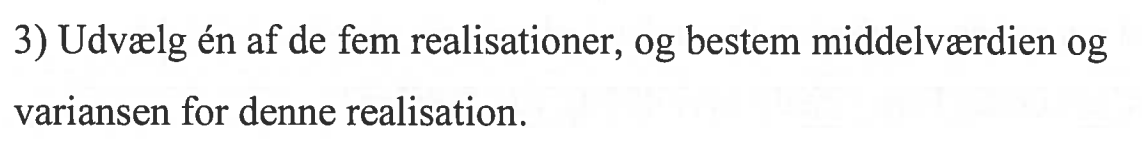

firstsRealisation = w(1)+4

firstsRealisation = 8.2451

Ex = firstsRealisation

Ex = 8.2451

% Varians = E[X^2] - E[X]^2
Ex2 = firstsRealisation^2

Ex2 = 67.9812

var = Ex2-Ex^2

var = 0

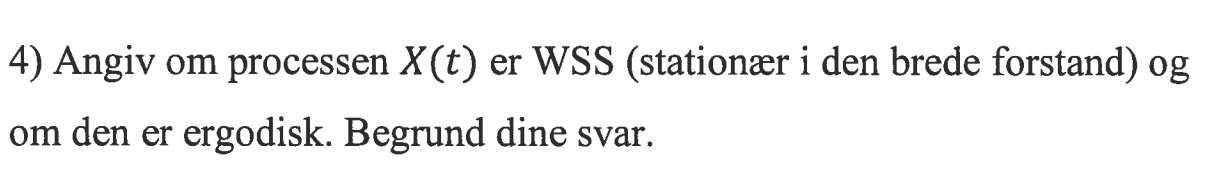

Da processen er uafhængig af tiden, og at middelværdien og variansen ikke ændrer sig, så kan vi konstanter at processen er stationær.

Processen er ikke ergodisk, da en realisation ikke siger noge om middelværdien, og variansen af hele prossen. 

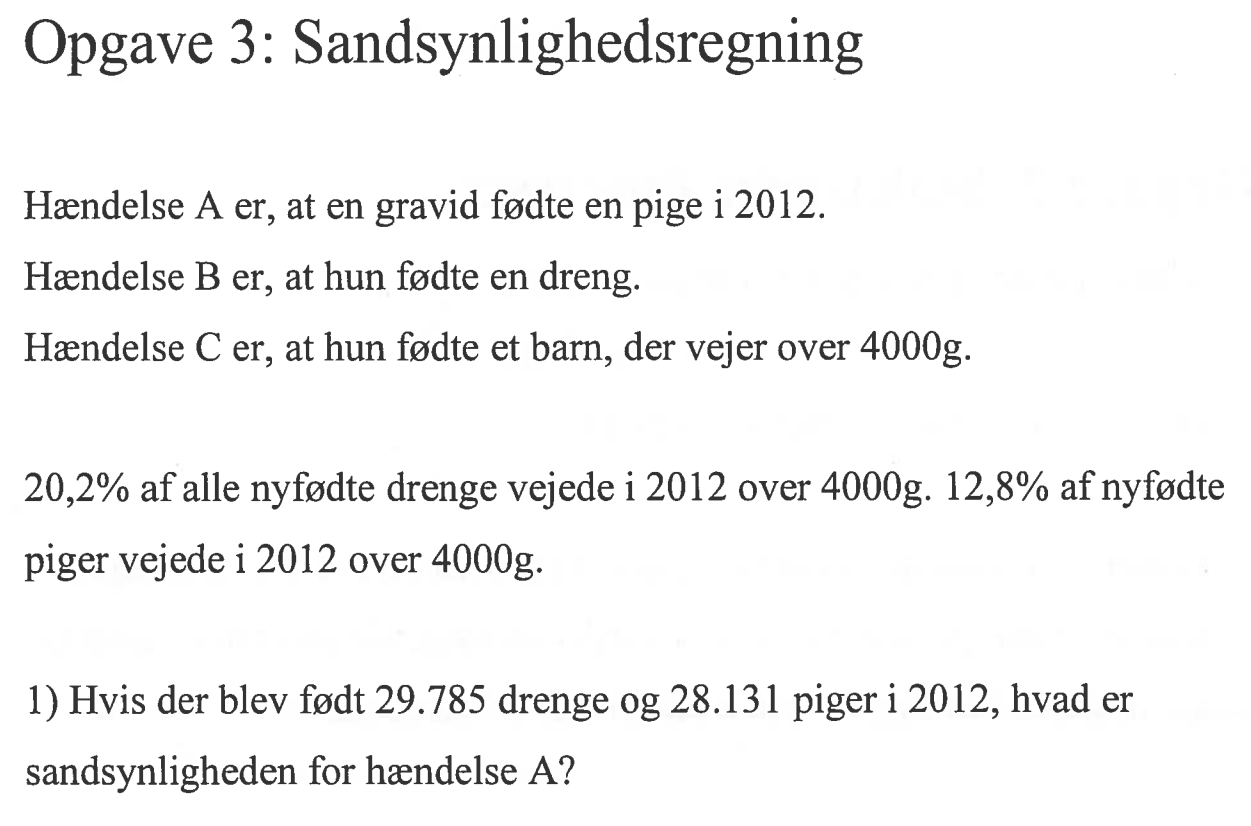

piger = 28131

piger = 28131

drenge = 29785

drenge = 29785

total = piger + drenge

total = 57916

Pr_a=piger/(total)

Pr_a = 0.4857

Total sandsynlighed er givet ved 

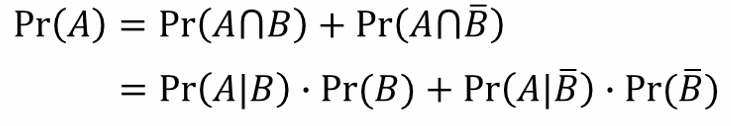

Pr_b= 1-Pr_a

Pr_b = 0.5143

Pr_C_A = 0.128

Pr_C_A = 0.1280

Pr_C_B = 0.202

Pr_C_B = 0.2020

Pr_C = ((Pr_C_A*Pr_a)+(Pr_C_B*Pr_b))

Pr_C = 0.1661

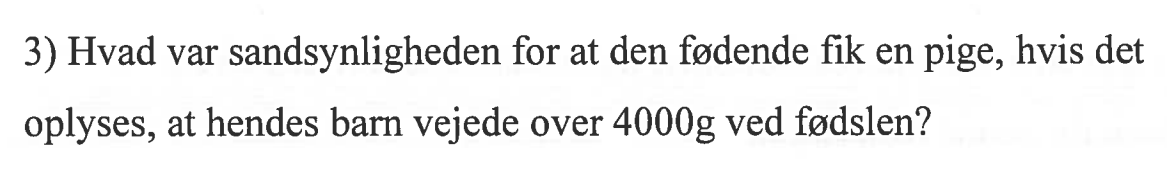

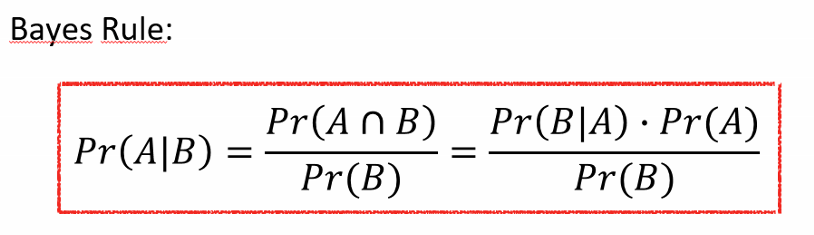

(Pr_C_A*Pr_a)/Pr_C

ans = 0.3744

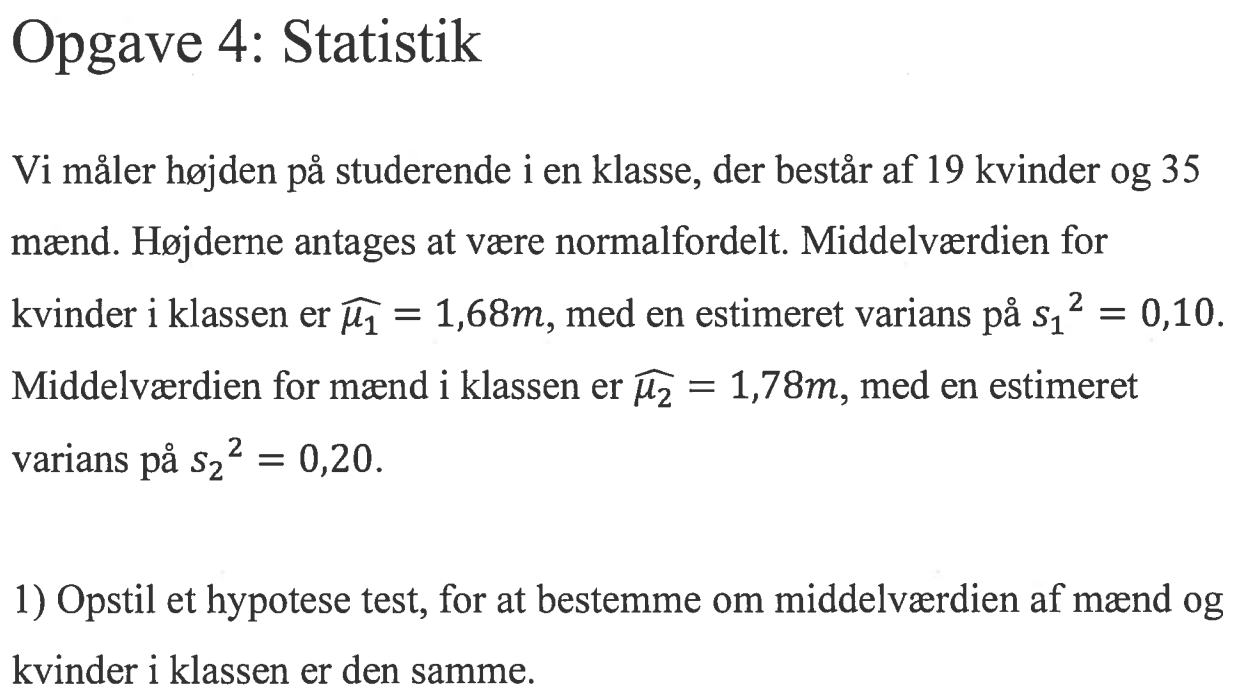

Null hypothesis. Brugt som testen af ingen forskel.


$$H_0 =\mu 1=\mu 2$$


Alternanive hypotese


$$H_1 =\mu 1\not= \mu 2$$


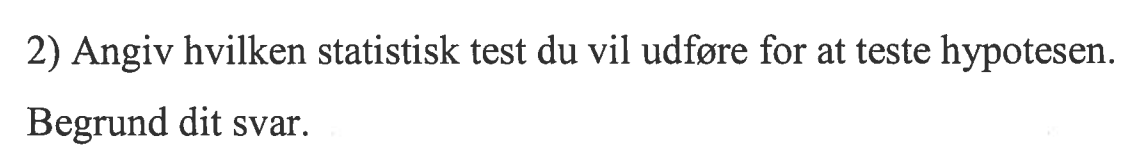

Da variansen er ukendt, og dataen er normalt fordelt, så bruges der en t-test på forskellen af middelværdierne. 

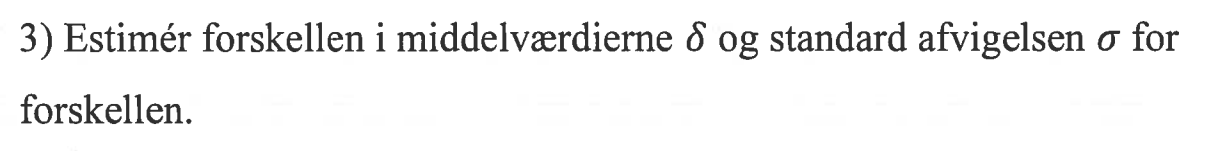

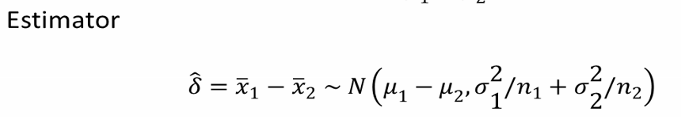

middel= abs(1.68-1.78)

middel = 0.1000

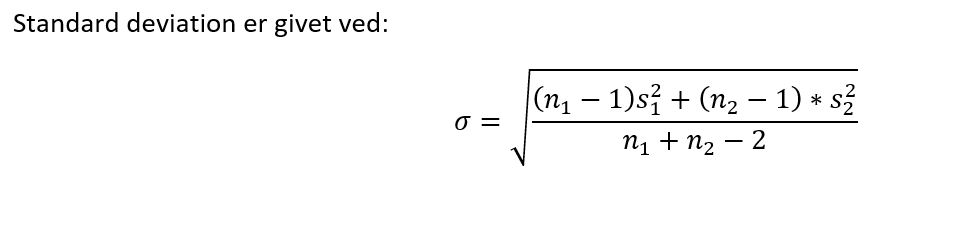

n1 = 19;
n2 = 35;
s1_2= 0.1;
s2_2 = 0.2;
standard=sqrt(((n1-1)*s1_2+(n2-1)*s2_2)/(n1+n2-2))

standard = 0.4067

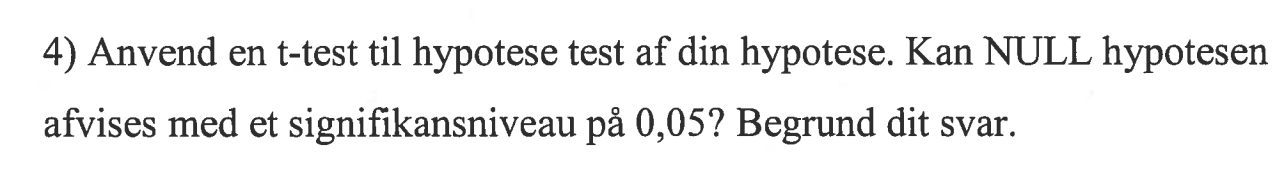

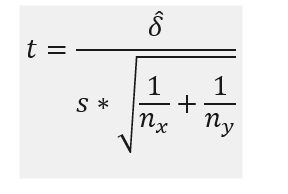

t = middel/(standard*sqrt((1/n1)+(1/n2)))

t = 0.8629

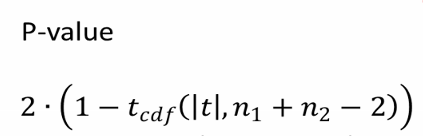

pval = 2*(1-tcdf(abs(t),(n1+n2)-2))

pval = 0.3921

Da pval > 0.05 så fejler vi med at afvise null hypotesen.

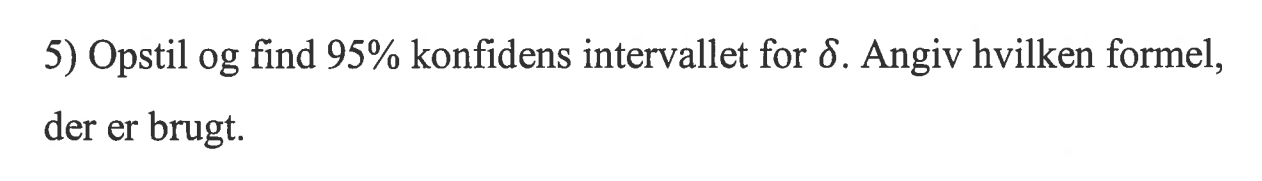

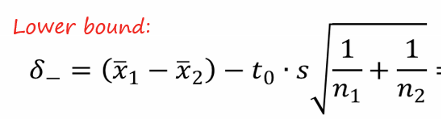

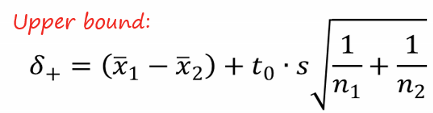

t0=tinv(1-0.05/2,(n1+n2-2))

t0 = 2.0066

koefMinus = middel-t0*standard*sqrt((1/n1)+(1/n2))

koefMinus = -0.1325

koefPositiv = middel+t0*standard*sqrt((1/n1)+(1/n2))

koefPositiv = 0.3325